# Basic oeprations

disp(6+4)

% Matrix inalization
A = [1 2; 3 4; 5 6]
v1 = [1 2 3]
v2 = [1;2;3]
v3 = 1:0.1:2 %start:step:end

% Other types of matrix
C = ones(2,3)
w1 = zeros(1,3)
r = rand(1,3)
w2 = -6 + sqrt(10)*(randn(1,100000))
hist(w2,50)
I = eye(5)

# Moving Data Around

A = [1 2; 3 4; 5 6]

A =      1     2
     3     4
     5     6


size(A)

ans =      3     2


size(A,1)

ans = 3

size(A,2)

ans = 2

length(A) %return the longest dimension

ans = 3

length([1;2;3;4;5]) % apply to the vector to get the size

ans = 5

## Load data

load('ex1data1.txt')
who % get all the variables


Your variables are:

A         X         m         v1        w1        
B         ans       n         v2        w2        
C         data      r         v3        y         
I         ex1data1  v         w         



size(ex1data1)

ans =     97     2


whos

  Name           Size                 Bytes  Class     Attributes

  A              3x2                     48  double              
  B              3x1                     24  double              
  C              3x4                     96  double              
  I              5x5                    200  double              
  X             97x1                    776  double              
  ans            1x2                     16  double              
  data          97x2                   1552  double              
  ex1data1      97x2                   1552  double              
  m              1x1                      8  double              
  n              1x1                      8  double              
  r              1x3                     24  double              
  v              1x5                     40  double              
  v1             1x3                     24  double              
  v2             3x1                     24  double              
  v3     

clear ex1data1 % clear the element
whos

  Name       Size                 Bytes  Class     Attributes

  A          3x2                     48  double              
  B          3x1                     24  double              
  C          3x4                     96  double              
  I          5x5                    200  double              
  X         97x1                    776  double              
  ans        1x2                     16  double              
  data      97x2                   1552  double              
  m          1x1                      8  double              
  n          1x1                      8  double              
  r          1x3                     24  double              
  v          1x5                     40  double              
  v1         1x3                     24  double              
  v2         3x1                     24  double              
  v3         1x11                    88  double              
  w          1x10                    80  double              
  w1   

load('ex1data1.txt')
v = ex1data1(1:5) % matlab index start from 1

v =     6.1101    5.5277    8.5186    7.0032    5.8598


save mydat.mat v  % save v to file mydat.dat
% save hello.txt v -ascii 

## Manipluate data

A = [1 2;3 4; 5 6]

A =      1     2
     3     4
     5     6


A(3,2)

ans = 6

A(2,:) % : means every element along that row/column

ans =      3     4


A(:,2)

ans =      2
     4
     6


A(:,1) % : means every elements along the column 1

ans =      1
     3
     5


A([1 3],:) % everything from 1 to 3 row

ans =      1     2
     5     6


A(:,2)

ans =      2
     4
     6


A(:,2) = [10;11;12]

A =      1    10
     3    11
     5    12


A = [A,[100;110;120]] % append another column

A =      1    10   100
     3    11   110
     5    12   120


B = [1 2 3;2 1 2;3 2 1]

B =      1     2     3
     2     1     2
     3     2     1


C = [A B] % Contcate AB

C =      1    10   100     1     2     3
     3    11   110     2     1     2
     5    12   120     3     2     1


D = [A;B] % ; means go to the next line

D =      1    10   100
     3    11   110
     5    12   120
     1     2     3
     2     1     2
     3     2     1


# Computing on Data

B = [11 12; 13 14; 15 16]

B =     11    12
    13    14
    15    16


C = [1 1; 1 3]

C =      1     1
     1     3


A = [1 2; 3 4; 5 6]

A =      1     2
     3     4
     5     6


A.*B % elementwise, dot product

ans =     11    24
    39    56
    75    96


A.^2 % elementwise

ans =      1     4
     9    16
    25    36


A' % transpose

ans =      1     3     5
     2     4     6


a = [1,2,3,4,5]

a =      1     2     3     4     5


val = max(a)

val = 5

[val,ind] = max(a)

val = 5

ind = 5

max(A) % columnwise

ans =      5     6


a < 3

ans = 1×5 logical array
   1   1   0   0   0


find(a < 3)

ans =      1     2


A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


[r,c] = find(A >=7)

r =      1
     3
     2


c =      1
     2
     3


sum(A)

ans =     15    15    15


max(A,[],1) % per row

ans =      8     9     7


max(A,[],2) % per col

ans =      8
     7
     9


max(max(A))

ans = 9

b = A(:)

b =      8
     3
     4
     1
     5
     9
     6
     7
     2


sum(A,1)

ans =     15    15    15


sum(A,2)

ans =     15
    15
    15


A.*eye(3) % get diagonal element

ans =      8     0     0
     0     5     0
     0     0     2


flipud(eye(3))

ans =      0     0     1
     0     1     0
     1     0     0


sum(sum(A.*eye(3)))

ans = 15


sum(sum(A.*flipud(eye(3))))

ans = 15

pinv(A) % inverse A

ans =     0.1472   -0.1444    0.0639
   -0.0611    0.0222    0.1056
   -0.0194    0.1889   -0.1028


# Visual Data

t = [0:0.01:0.98]

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


y1 = sin(2*pi*4*t)

y1 =          0    0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    0.9823    0.9048    0.7705    0.5878    0.3681    0.1253   -0.1253   -0.3681   -0.5878   -0.7705   -0.9048   -0.9823   -0.9980   -0.9511   -0.8443   -0.6845   -0.4818   -0.2487   -0.0000    0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    0.9823    0.9048    0.7705    0.5878    0.3681    0.1253   -0.1253   -0.3681   -0.5878   -0.7705   -0.9048   -0.9823   -0.9980   -0.9511   -0.8443   -0.6845   -0.4818   -0.2487


plot(t,y1)
y2 = cos(2*pi*4*t)

y2 =     1.0000    0.9686    0.8763    0.7290    0.5358    0.3090    0.0628   -0.1874   -0.4258   -0.6374   -0.8090   -0.9298   -0.9921   -0.9921   -0.9298   -0.8090   -0.6374   -0.4258   -0.1874    0.0628    0.3090    0.5358    0.7290    0.8763    0.9686    1.0000    0.9686    0.8763    0.7290    0.5358    0.3090    0.0628   -0.1874   -0.4258   -0.6374   -0.8090   -0.9298   -0.9921   -0.9921   -0.9298   -0.8090   -0.6374   -0.4258   -0.1874    0.0628    0.3090    0.5358    0.7290    0.8763    0.9686


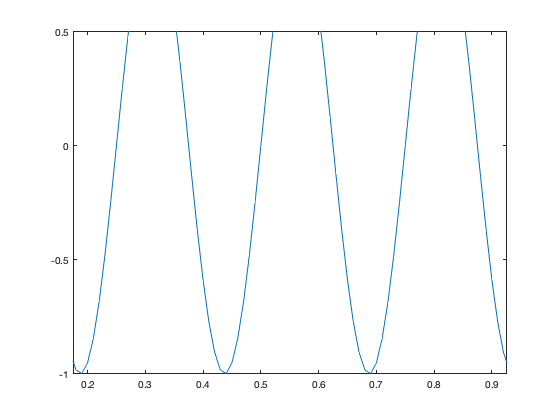

plot(t,y2)
plot(t,y1)
hold on
plot(t,y2,'r')
xlabel('time')
ylabel('value')
legend('sin','cos')
title('my plot')
% print -dpng 'myplot.png'
close

figure(1)
plot(t,y1)

figure(2)
plot(t,y2)
close
subplot(1,2,1) % 1 row 2 column, first pic is 
plot(t,y1)
subplot(1,2,2)
plot(t,y2)
axis([0.5 1 -1 1])
A = magic(5)

A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


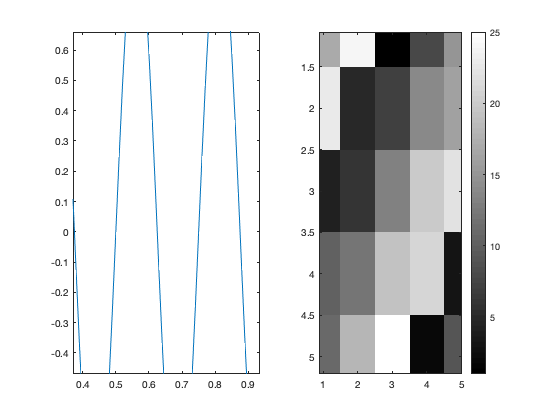

imagesc(A), colorbar, colormap gray;

# Control Statements

for i = 1:10,
    v(i)=2^i;
end

indices = 1:10

indices =      1     2     3     4     5     6     7     8     9    10


for i = indices,
    disp(i);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



while i<=5,
    v(i) = 100;
end

if v(1) == 1.
    disp('value is 1')
elseif v(1) == 2,
    disp('value is 2')
else
    disp('not one or two')
end

value is 2


function [y1,y2] = squareThisNumber(x)
    y2 = x*x;
    y1 = x
end
y is the return
[a,b] = squareThisNumber(x), a,b

